# Bifurcation diagram for a Berkolaiko-Marzuola-Pelinovsky quantum graph

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

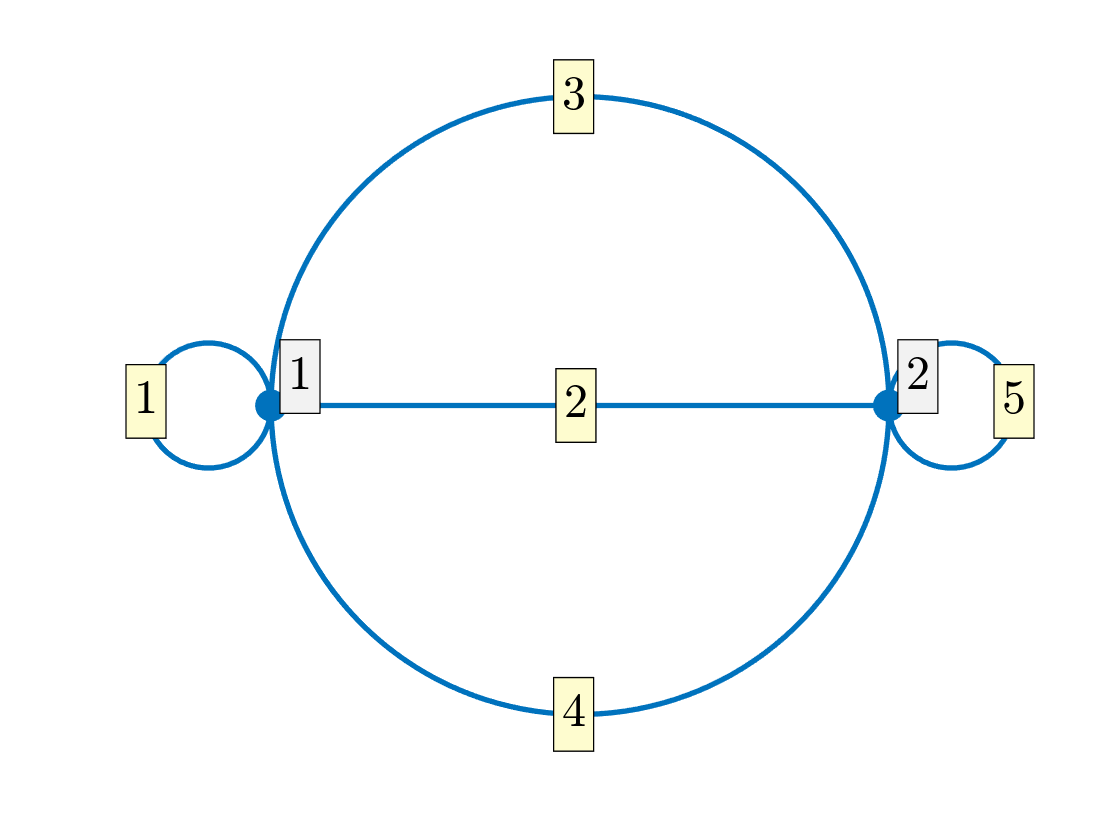

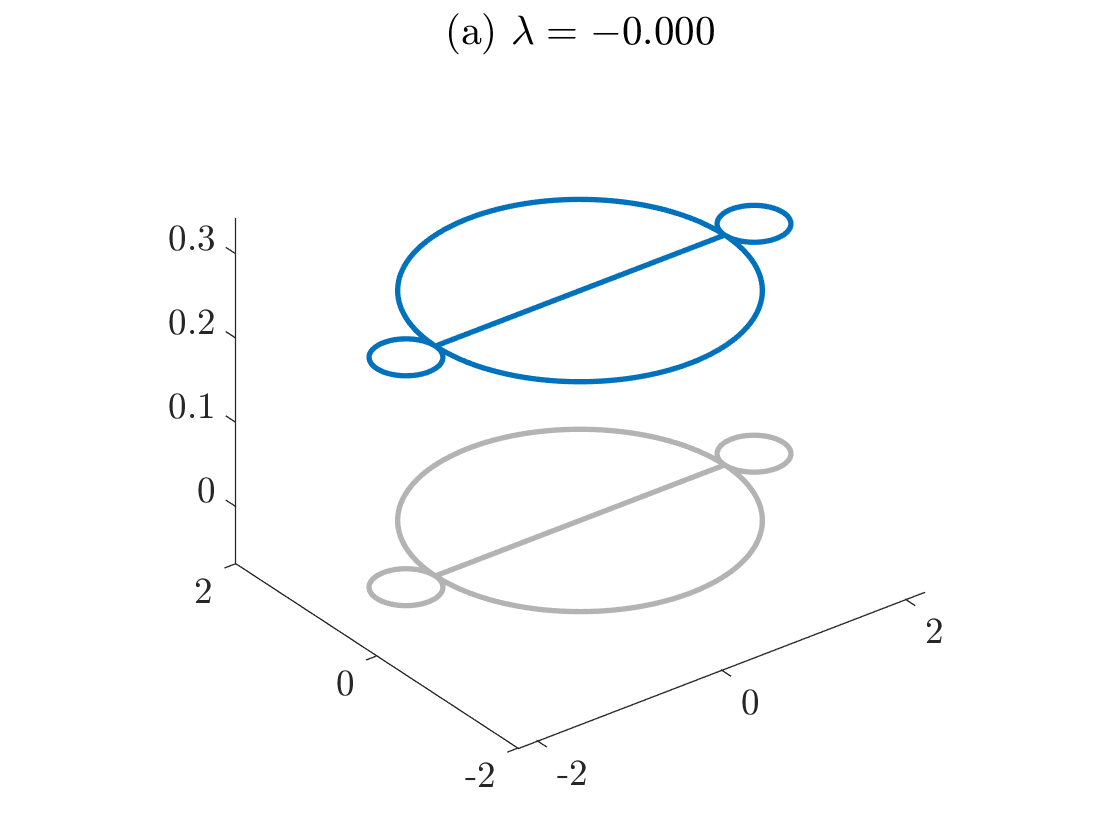

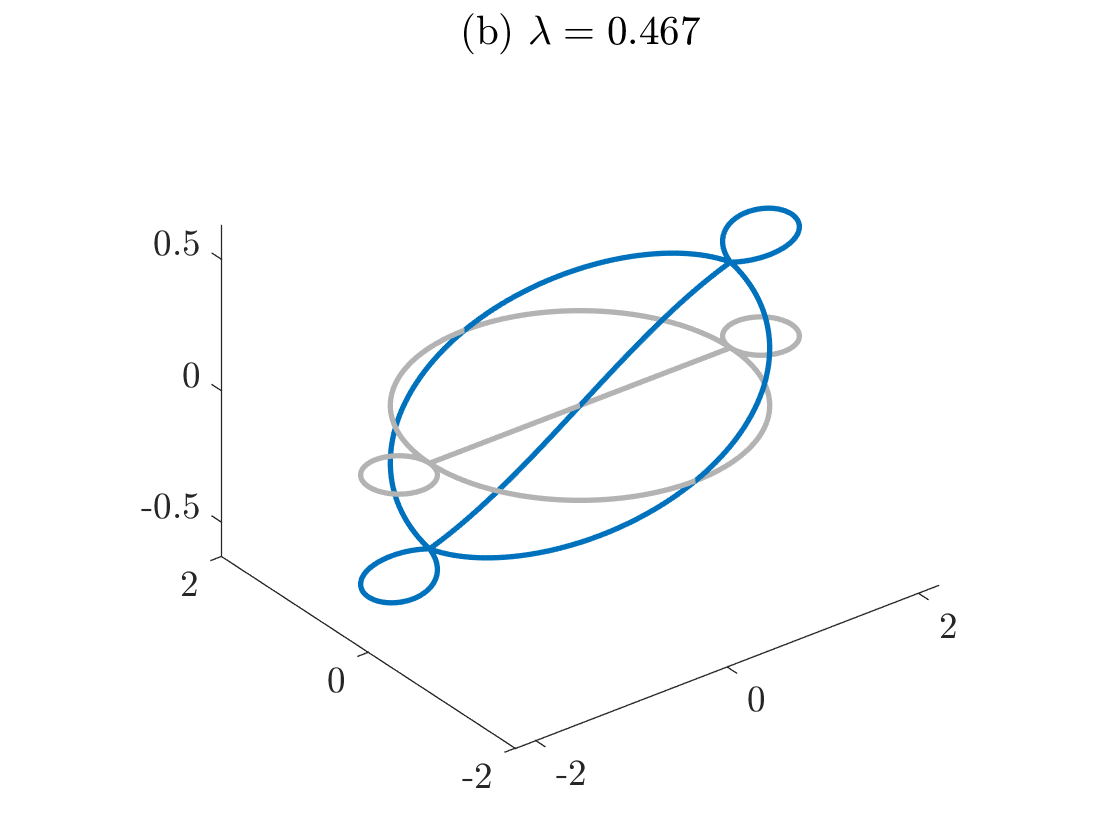

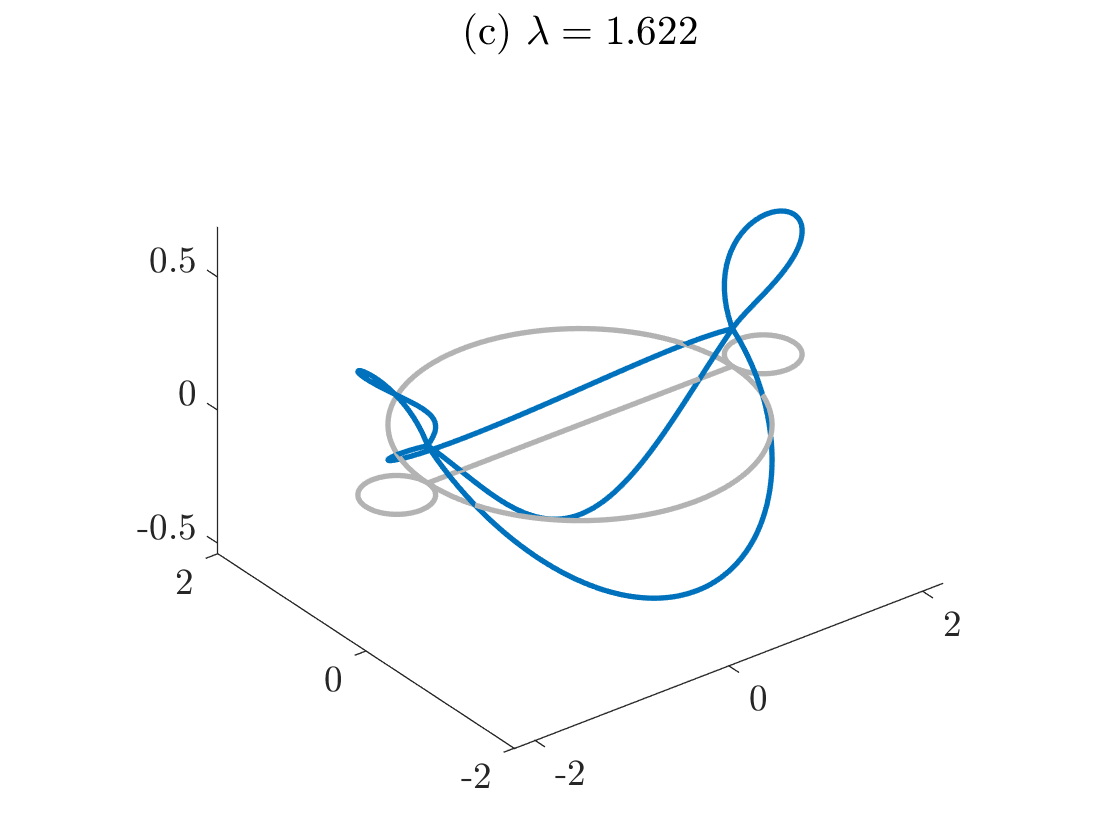

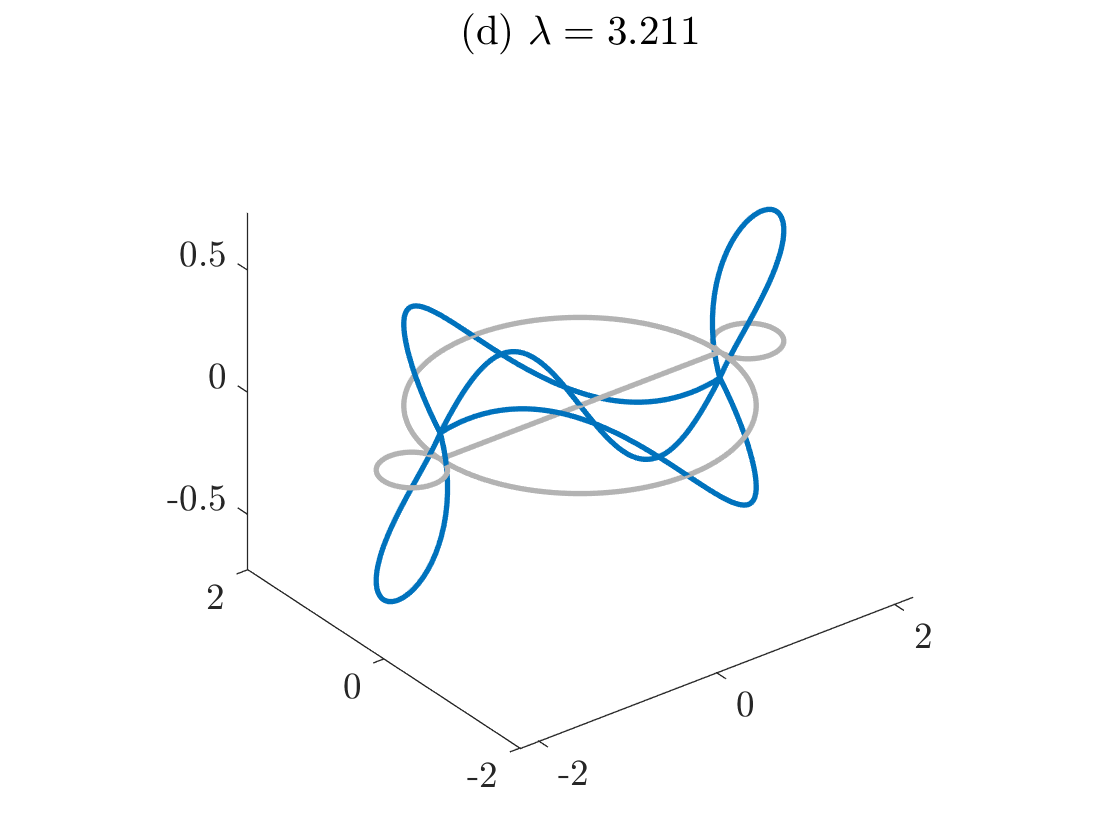

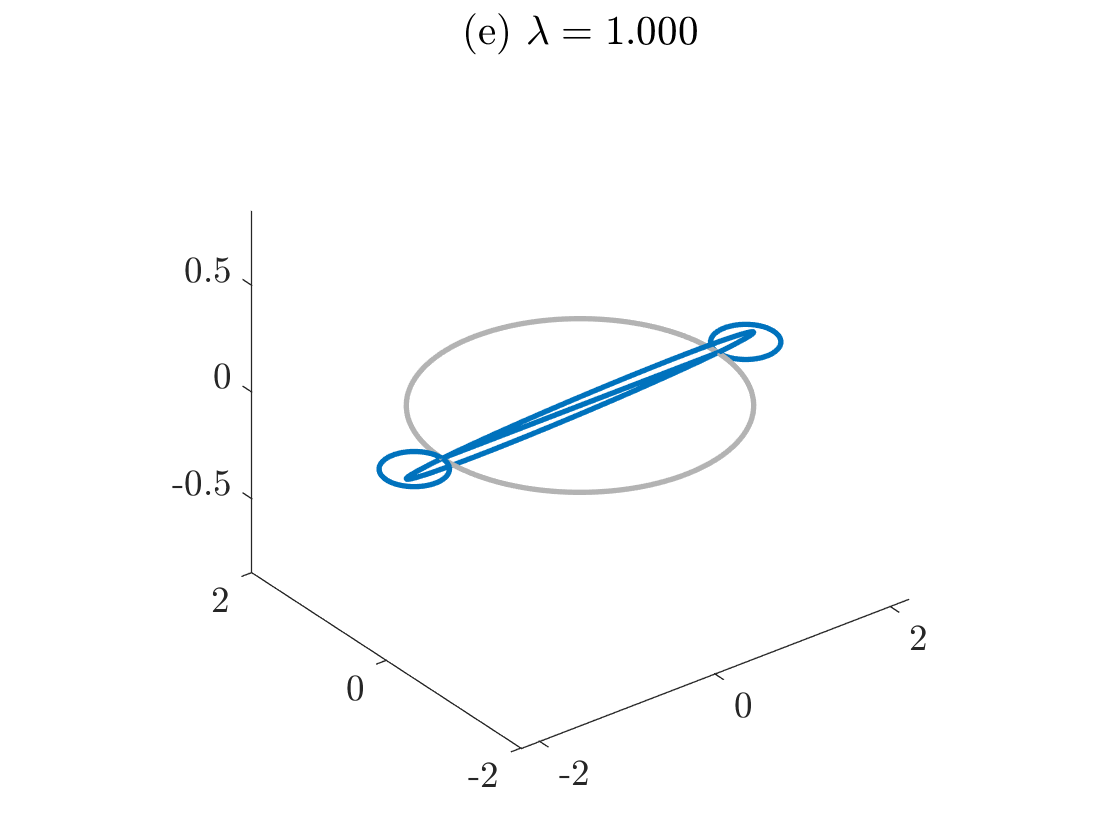

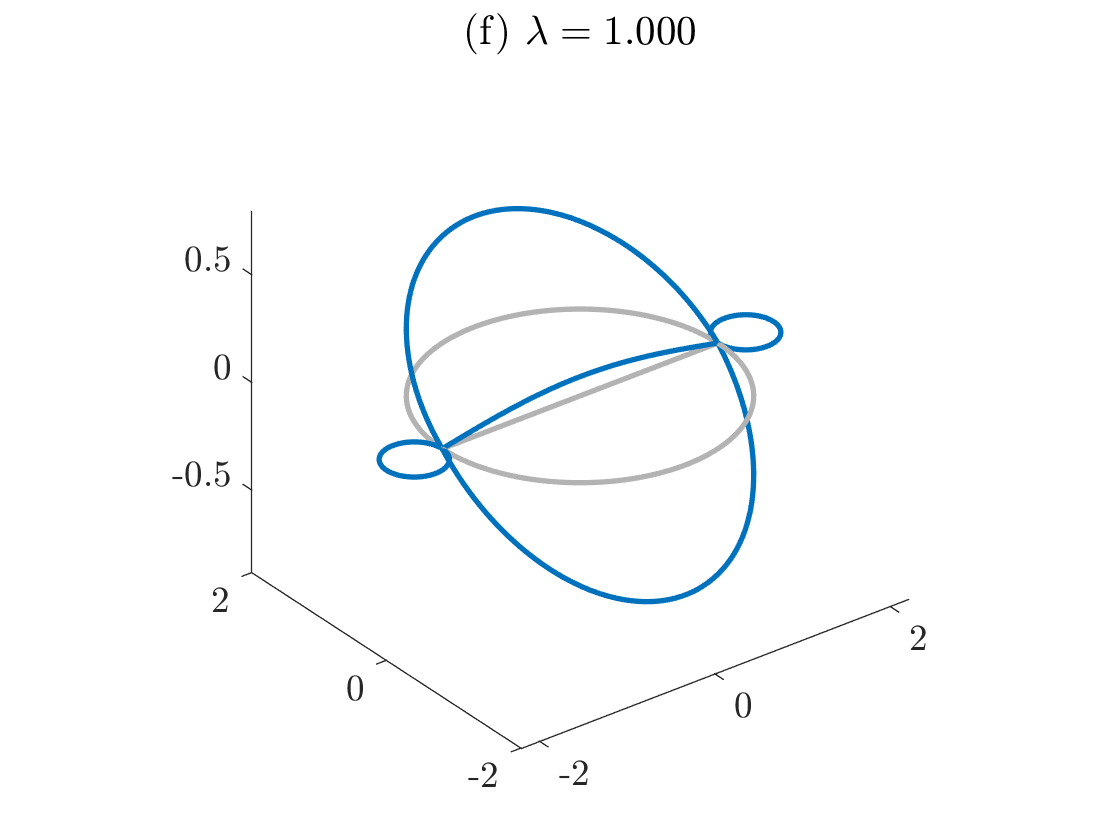

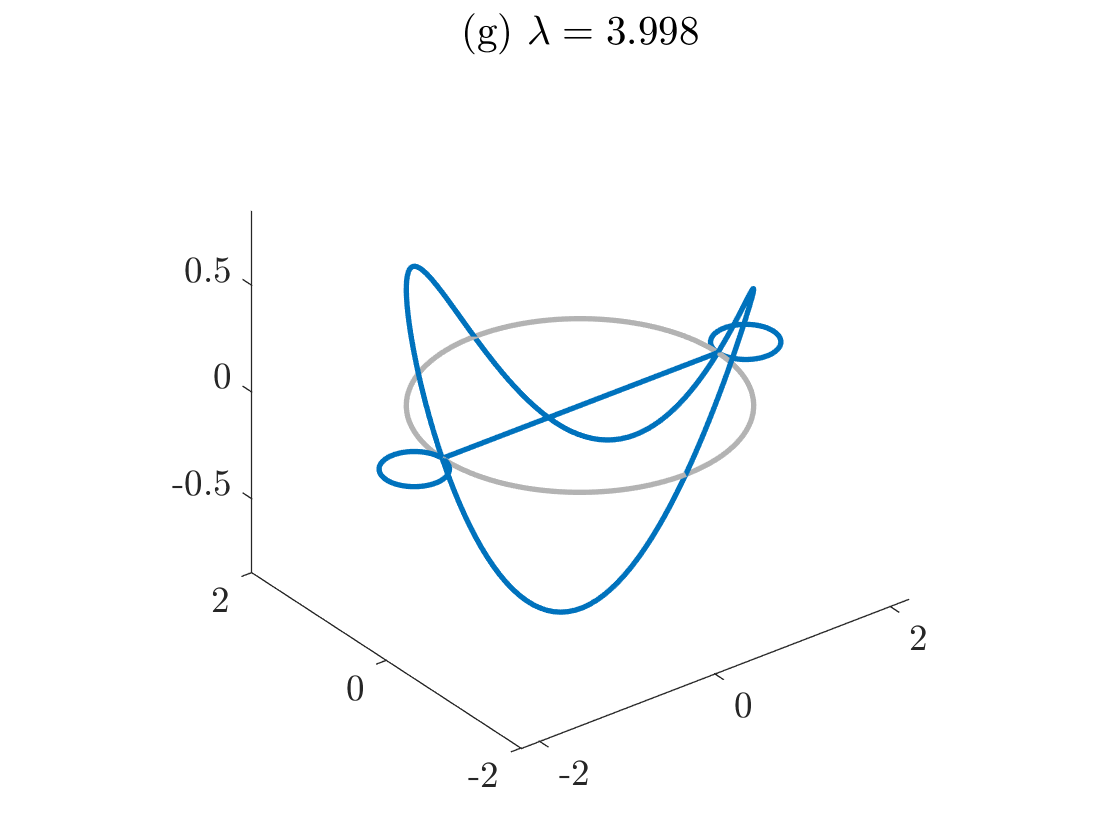

Saved to directory data\BMP\001.
Run number is 1.


tag='BMP';
Phi=quantumGraphFromTemplate(tag); % use the default values

nToPlot=4;
nDoubles=2;
nTriples=0;

diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-2,'NThresh',10,'plotFlag',false,'maxTheta',1.5);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\BMP\001\branch001.
Branching Bifurcation at solution number 8.
Branching Bifurcation at solution number 14.
Branching Bifurcation at solution number 19.


## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\BMP\001\branch002.
No branching bifurcations found.


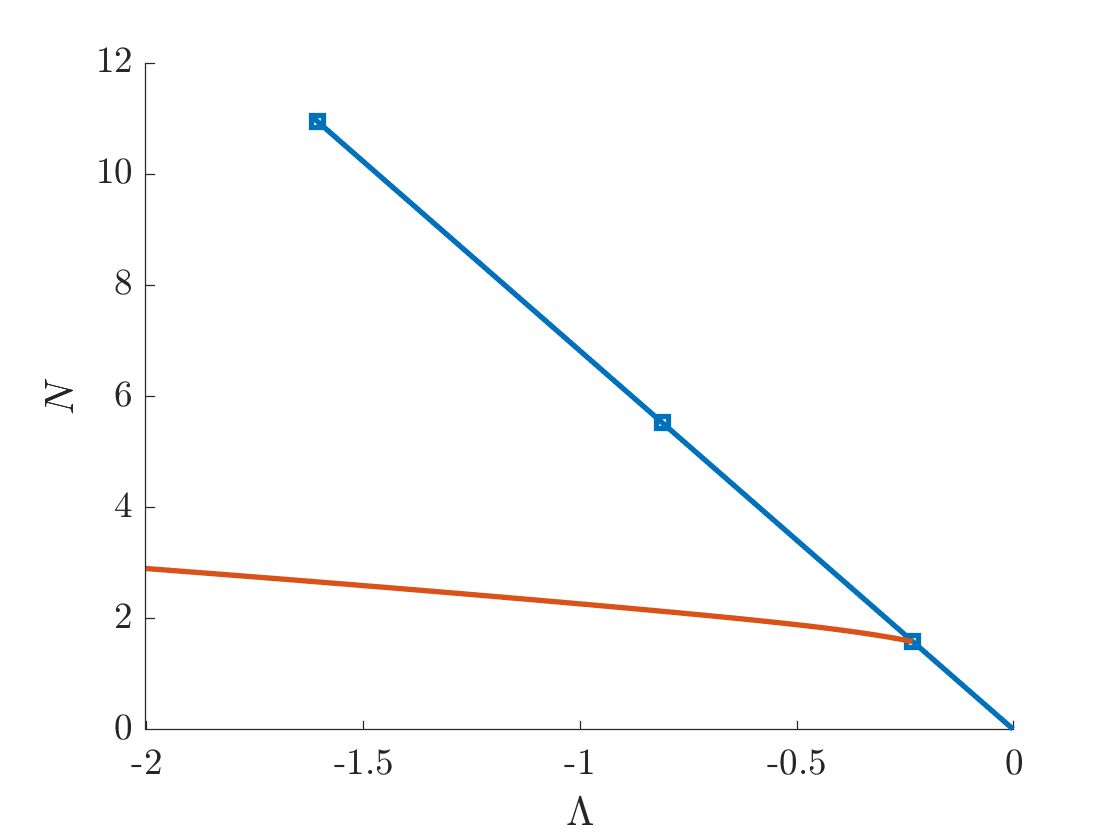

bifurcationDiagram(tag,diagramNumber)

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in `bn1` at bifurcation location` bl1(2)`

[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data\BMP\001\branch003.
No branching bifurcations found.


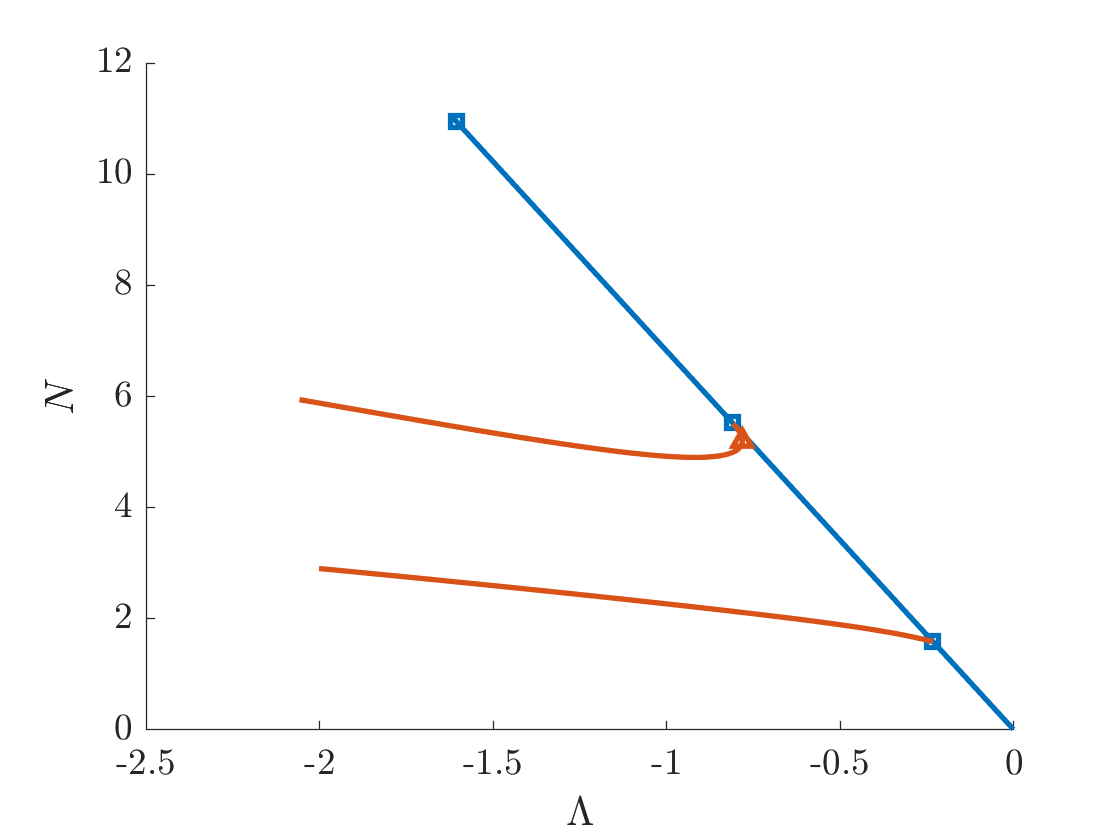

bifurcationDiagram(tag,diagramNumber)

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data\BMP\001\branch004.
No branching bifurcations found.


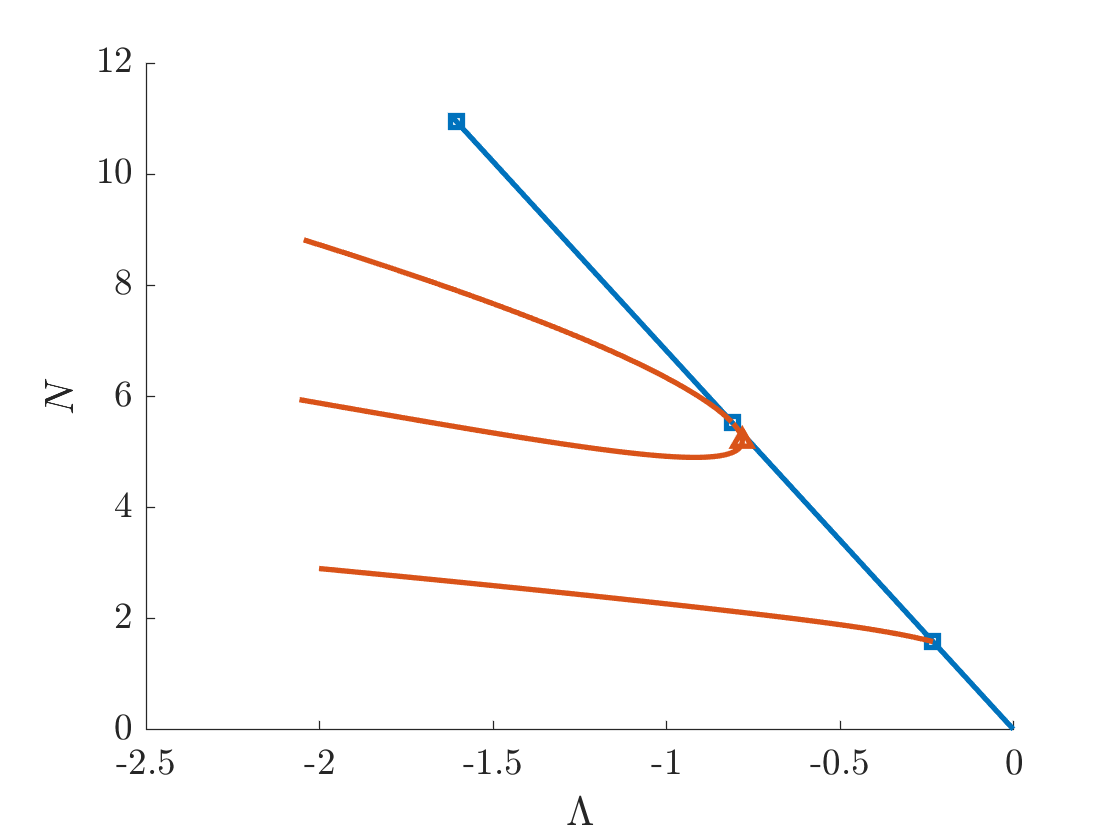

bifurcationDiagram(tag,diagramNumber)

## Compute a large-amplitude solution, save it to a file, and compute its continuation

Lambda0 = -4;
edges = [1 2 5];
signs = [1 1 1];
filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,Lambda0,edges,signs);

File saved to data\BMP\001\savedFunction.001.
File number is 1. 


options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn5,bl5]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);

N threshold crossed.
Branch number 5.
Data saved to directory data\BMP\001\branch005.
Branching Bifurcation at solution number 33.
Branching Bifurcation at solution number 142.
Branching Bifurcation at solution number 166.


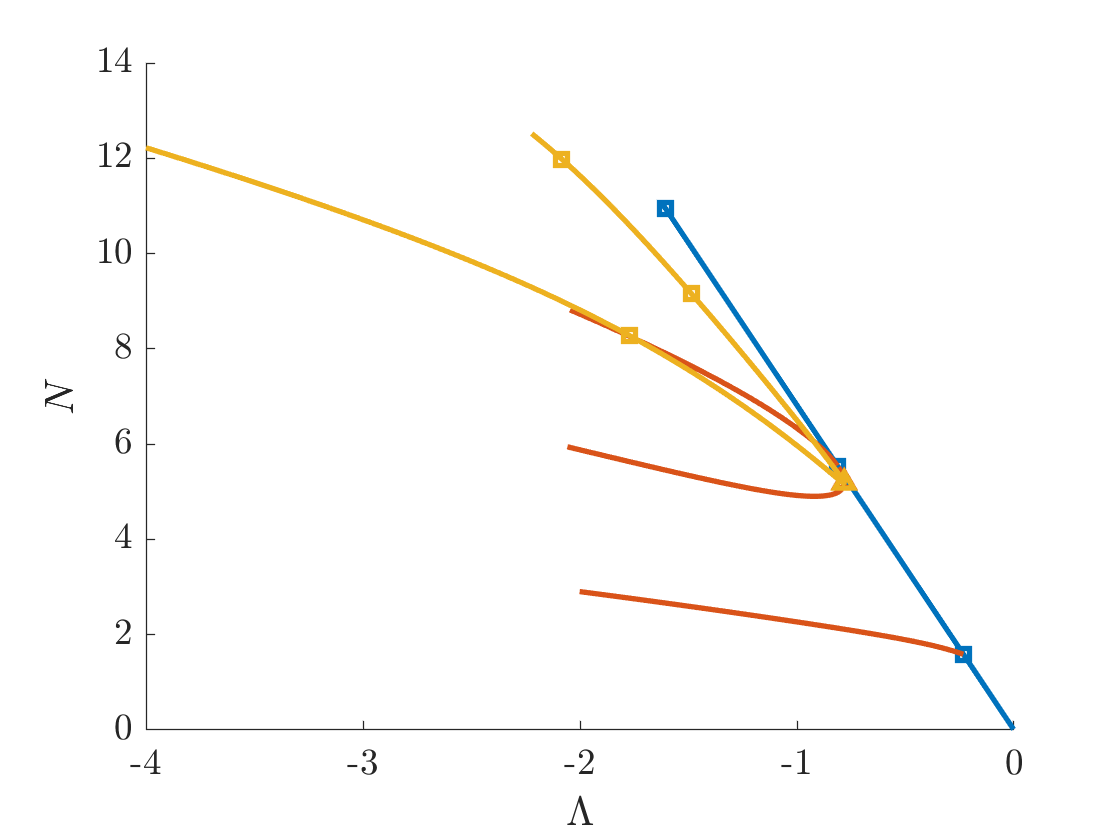

bifurcationDiagram(tag,diagramNumber)

## Plot some solutions

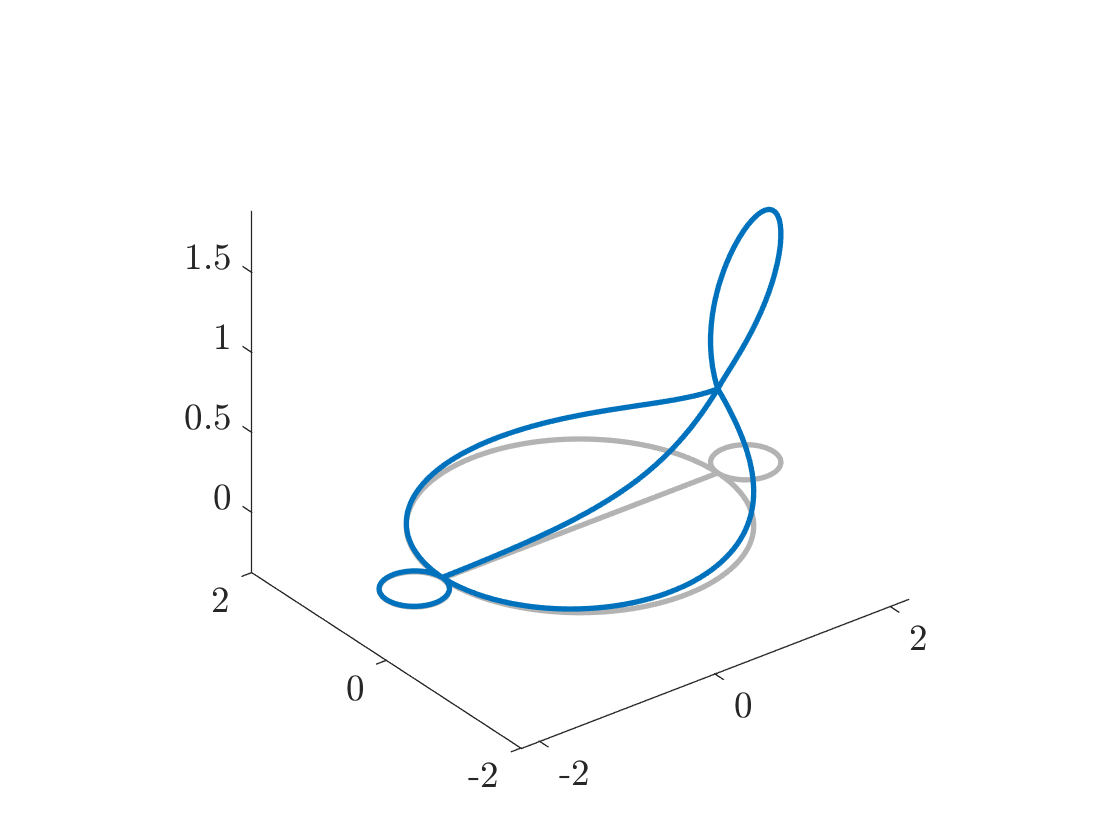

plotSolution(tag,diagramNumber,bn2,'last')

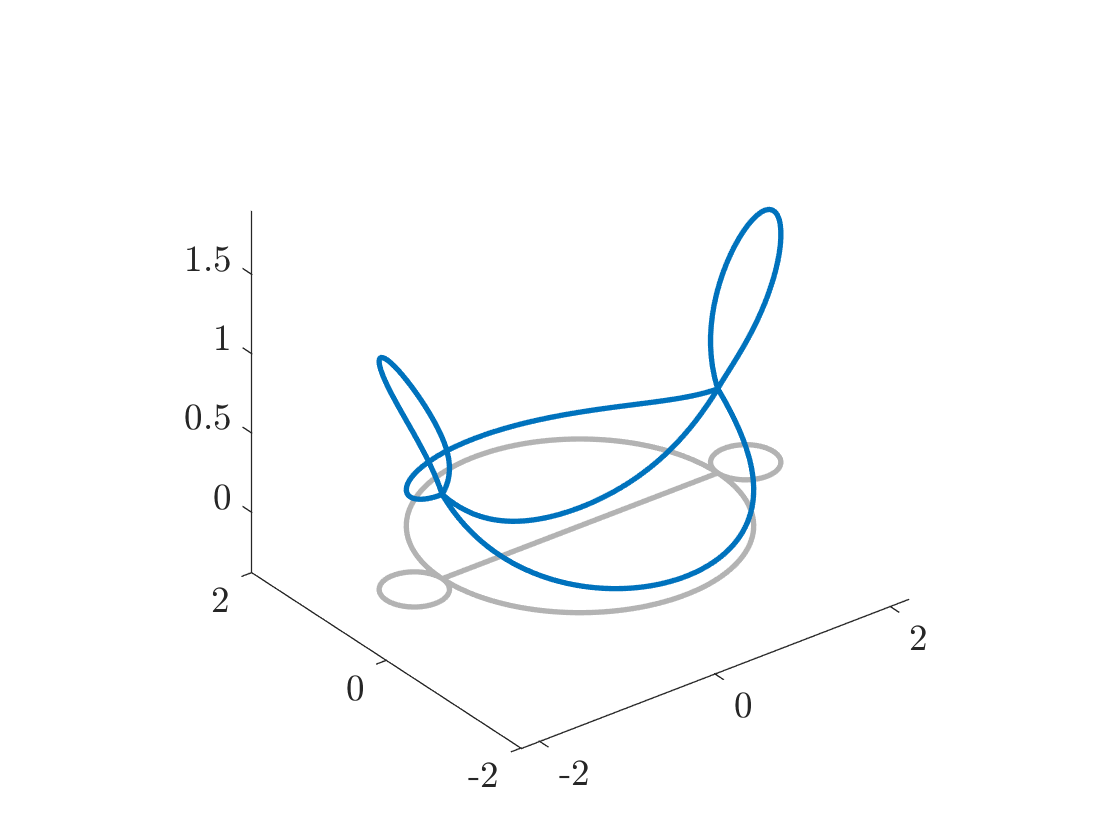

plotSolution(tag,diagramNumber,bn3,'last')

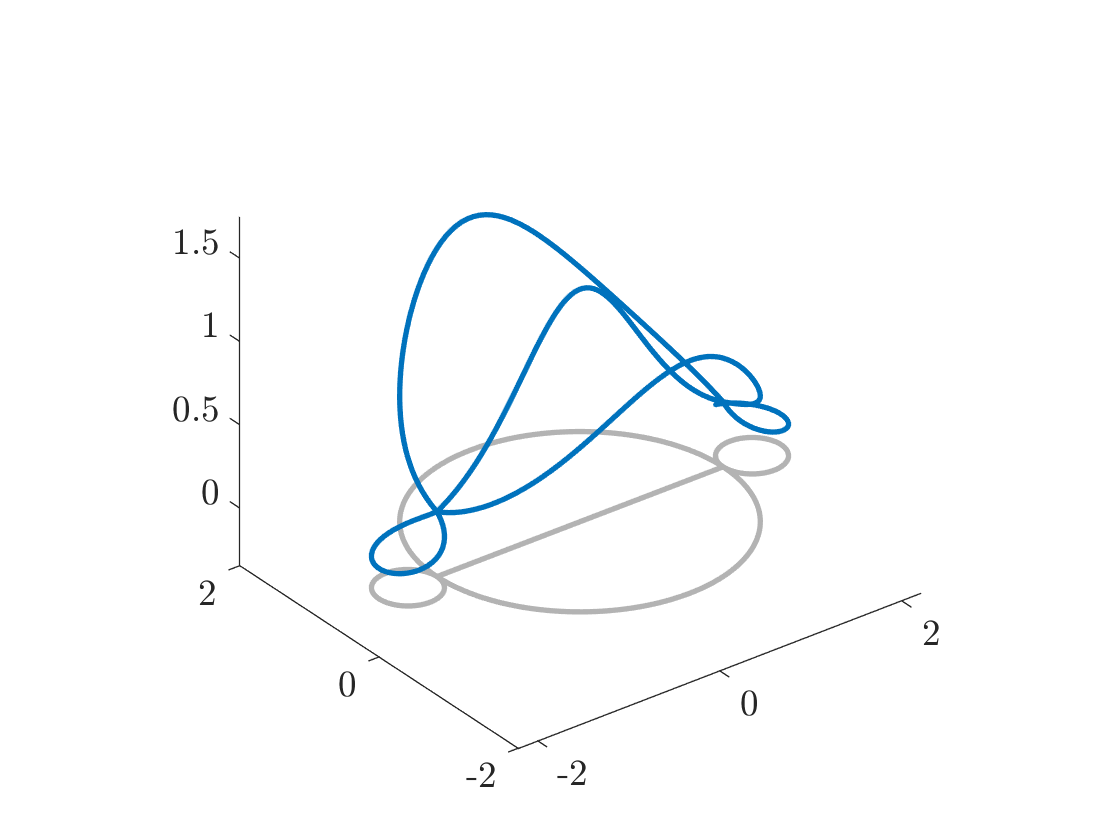

plotSolution(tag,diagramNumber,bn4,'last')